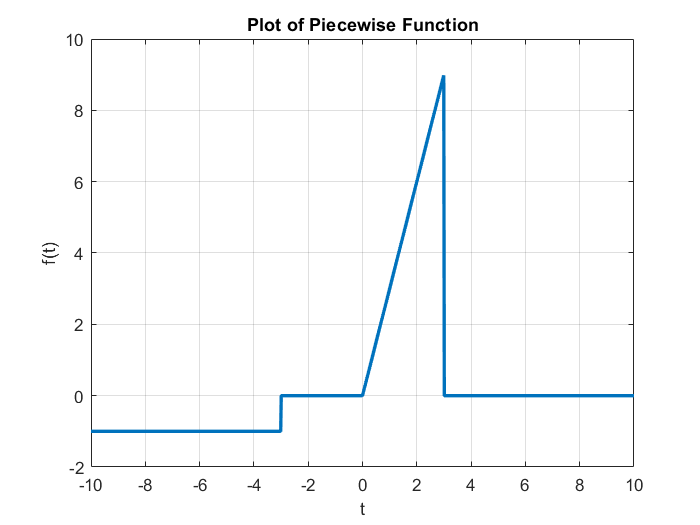


% Define the range of t from -10 to 10 with 1000 points for smooth plotting
t = linspace(-10, 10, 1000);

% Initialize the function f(t) with zeros
f = zeros(size(t));

% Define the function using piecewise conditions
for i=1:length(t)
    if t(i) < -3
        f(i) = -1; % f(t) = -1 for t < -3
    elseif t(i) >= -3 && t(i) <= 3
        f(i) = 3 * max(0, t(i)); % f(t) = 3 * max(0, t) for -3 <= t <= 3
    else
        f(i) = exp(-2.5 * t(i)); % f(t) = exp(-2.5 * t) for t > 3
    end
end

% Create a new figure window for the plot
figure;

% Plot the function f(t) versus t with a line width of 2 for better visibility 
plot(t, f, 'LineWidth', 2);
xlabel('t'); % Label the x-axis as 't'
ylabel('f(t)'); % Label the y-axis as 'f(t)'
ylim([-2, 10]); % start y from -2 to see the plot better
title('Plot of Piecewise Function'); % Add a title to the plot
grid on; % Turn on the grid for easier visualization